# **Tutorial 9**: a solar array with 3 pannels ( run $\le 1\;mn$)

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

Let us consider a solar array $\mathcal{SA}$ composed of 3 identical pannels $\mathcal A_i$, $i=1,\cdots 3$. Each pannel is modelled by the generic plate model already used in [***tutorial 8***](matlab:open('../Tutorial8/tutorial8.html')) and corresponds to a quare plate  ( $1\,m\times 1\,m\times 0.01\,m$) of aluminium.

web DocPlate_joly.html -new

The connection points between the 3 pannels are described in the following Figure:

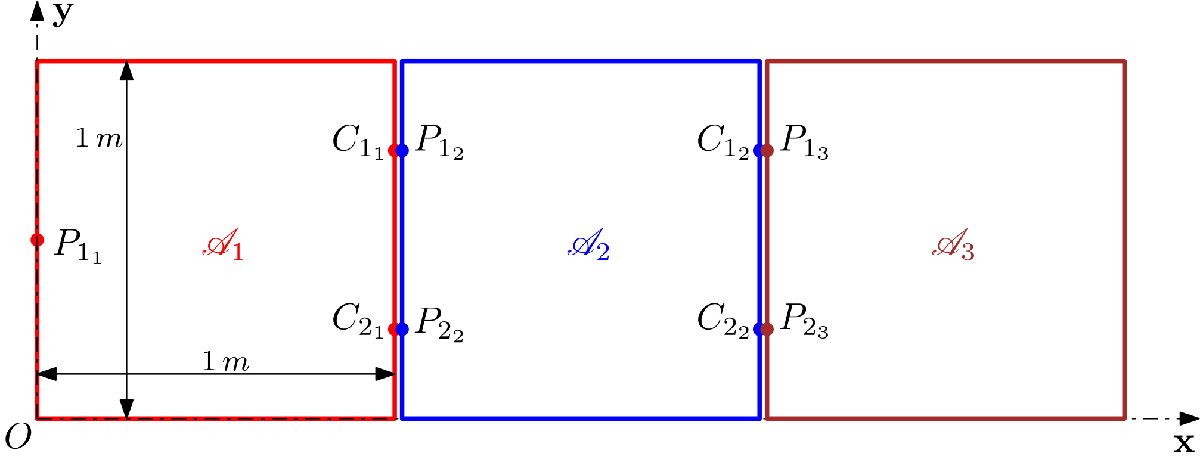

- $\mathcal A_1$ have 1 parent point $P_{1_1}$ and 2 child points $C_{1_1}$ and $C_{2_1}$

- $\mathcal A_2$ have 2 parent points $P_{1_2}$ and $P_{2_2}$ (where the 2 dual acceleration twists are imposed by $\mathcal A_1$) and 2 child points $C_{1_2}$ and $C_{2_2}$,

- $\mathcal A_3$ have 2 parent points $P_{1_3}$ and $P_{2_3}$  (where the 2 dual acceleration twists are imposed by $\mathcal A_2$).

The hinges at the connection points ( $P_{1_j}\equiv C_{1_{j-1}}$, $P_{2_j}\equiv C_{2_{j-1}}$, $j=2,3$)  are assumed to be rigid.

## 2. Model using the `SDTlib`

The $6\times 18$ model $\mathbf M^{\mathcal{SA}}_{P_{1_1}}(\mathrm s)$ of the whole array $\mathcal{SA}$ between the the [motion vector](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html')) $[\delta\mathbf m^{\mathcal A_1}_{P_{1_1}}]_{\mathcal R_{a_1}}$ prescribed at point $P_{1_1}$ by the parent structure and the wrench $[\mathbf W_{./\mathcal A_1,P_1}]_{\mathcal R_{a_1}}$ applied by $\mathcal{SA}$on this parent structure at point $P_{1_1}$ is decribed by the direct interconnection of the NINOP model of the 3 pannels $\mathcal A_i$:

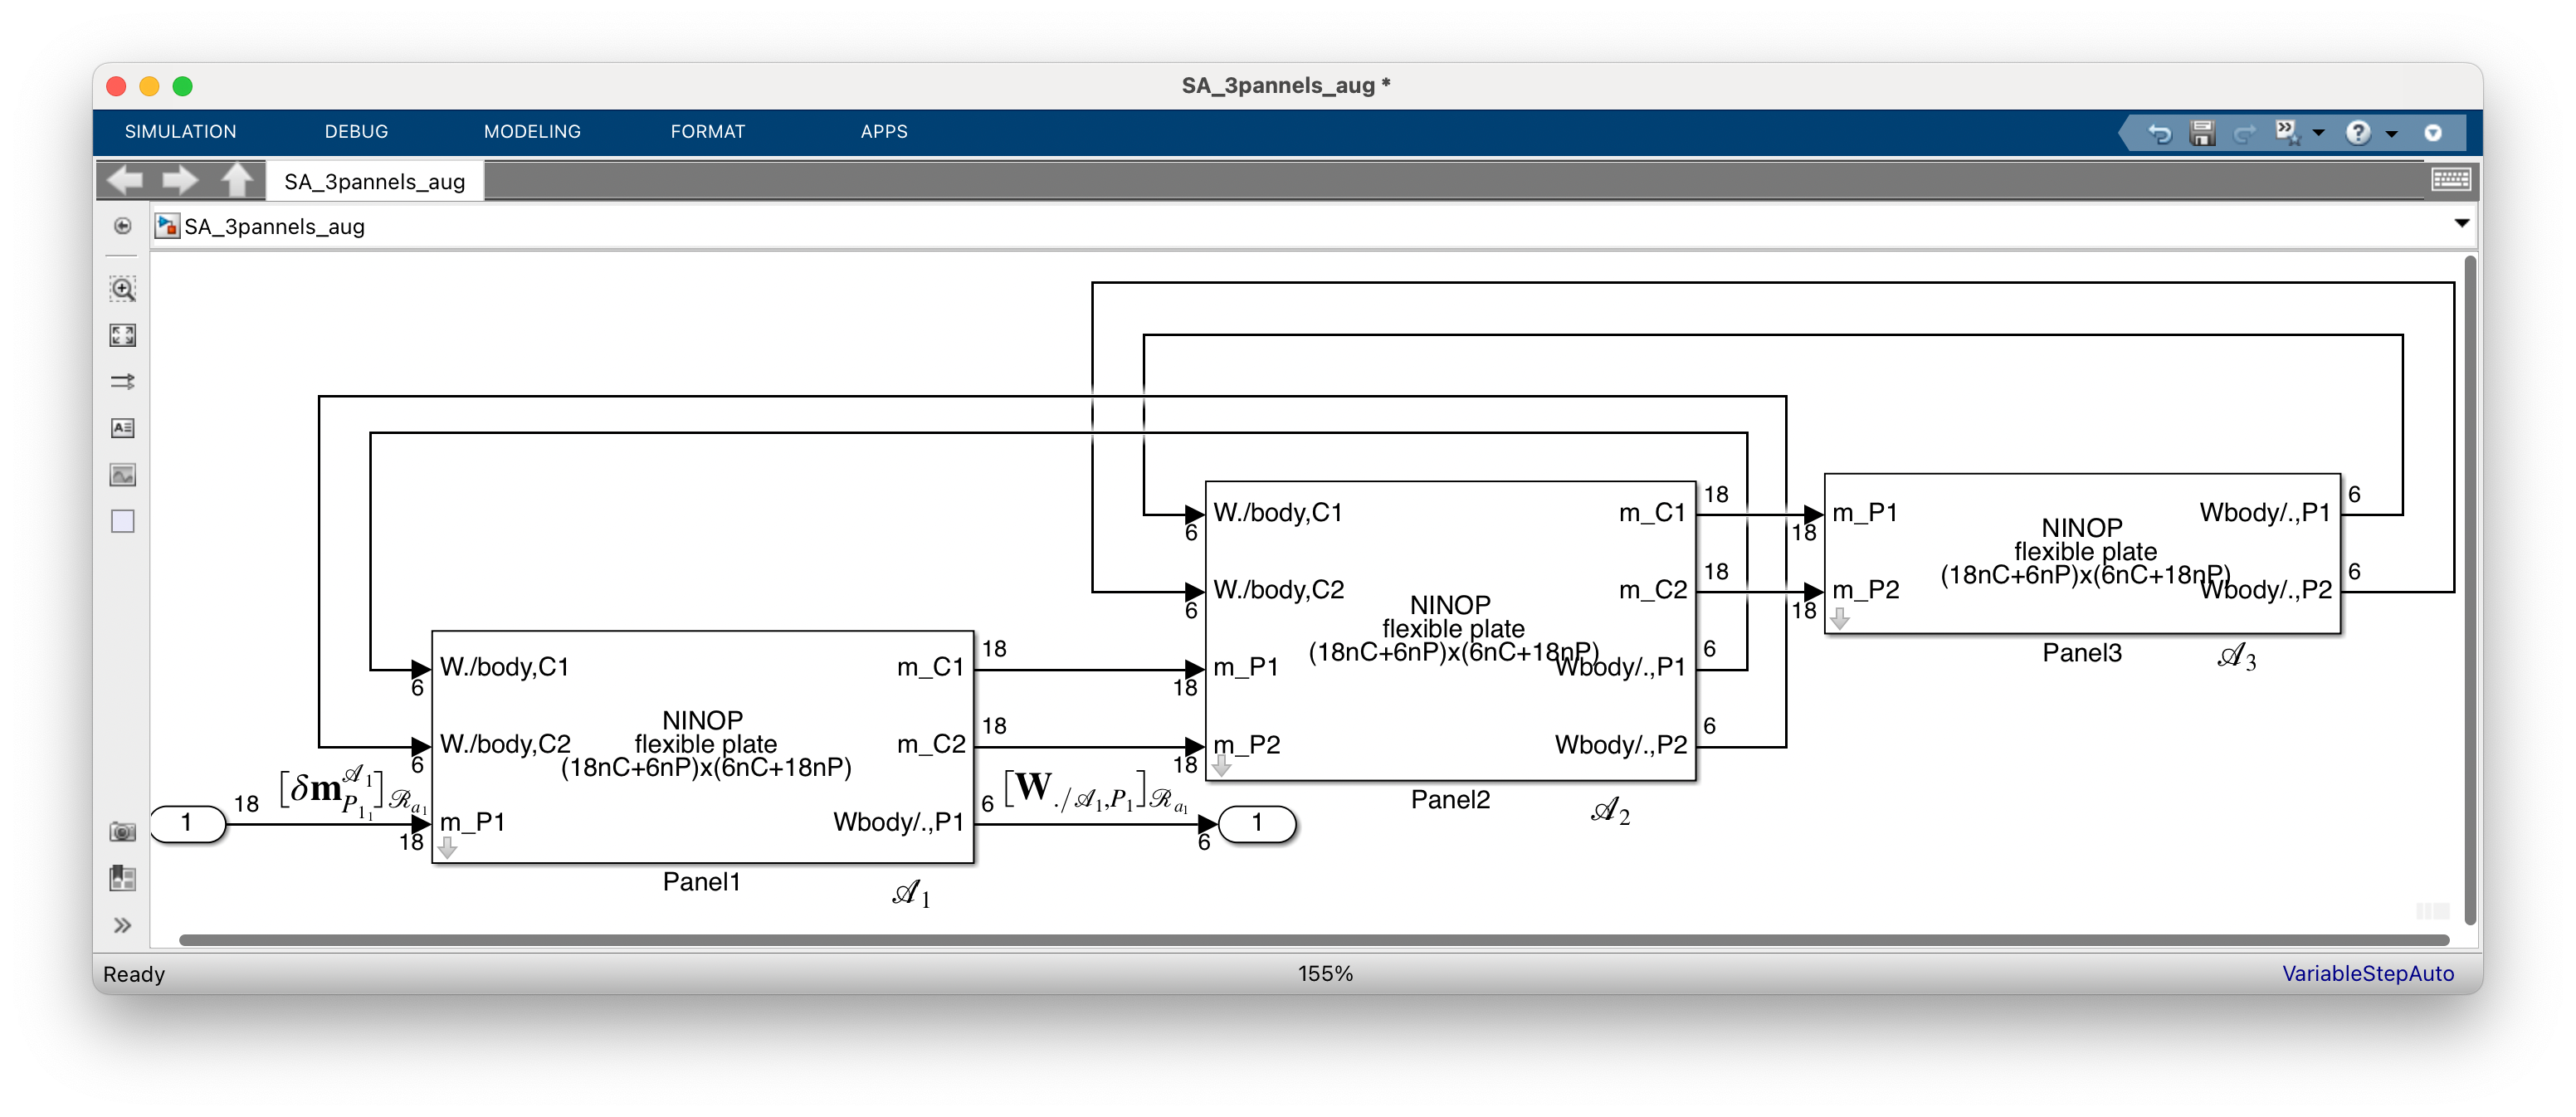

SA_3pannels_aug
M_SA=linearize('SA_3pannels_aug');

One can check that the DC gain of thie transfer from the $6$ accelaration inputs (the first $6$ components of the motion vector $[\delta\mathbf m^{\mathcal A_1}_{P_{1_1}}]_{\mathcal R_{a_1}}$) to the wrench $[\mathbf W_{./\mathcal A_1,P_1}]_{\mathcal R_{a_1}}$ corresponds (with a minus sign) to the mass/inertia at the point $P_{1_1}$ of a rectangular plate ( $3\,m\times 1\,m \times 0.01\,m$) of aluminium:

L=3;l=1;h=0.01;rho=474;
M_SA_G=L*l*h*rho;
I_SA_G=M_SA_G/12*diag([l^2 L^2 l^2+L^2]);
D_SA_G=[M_SA_G*eye(3) zeros(3);zeros(3) I_SA_G];
D_SA_P1=translate_dynamic_model([L/2;l/2;0],[0;l/2;0],D_SA_G)

D_SA_P1 =    14.2200         0         0         0         0         0
         0   14.2200         0         0         0   21.3300
         0         0   14.2200         0  -21.3300         0
         0         0         0    1.1850         0         0
         0         0  -21.3300         0   42.6600         0
         0   21.3300         0         0         0   43.8450


-dcgain(M_SA(:,1:6))

ans =    14.2200   -0.0000         0         0         0   -0.0000
   -0.0000   14.2200         0         0         0   21.3300
         0         0   14.2200   -0.0000  -21.3300         0
         0         0   -0.0000    1.1851    0.0000         0
         0         0  -21.3300    0.0000   42.6601         0
   -0.0000   21.3300         0         0         0   43.8450


One can also check the dynamics $\mathbf M^{\mathcal{SA}}_{P_{1_1}}(\mathrm s)$ reveals $n_{at\;0}=12$ eigenvalues around $0$. Exactly as in the academic case presented in [***tutorial 5***](matlab:open('../Tutorial5/tutorial5.html')) (in the single axis case) these eigenvalues are due to the kinematics constraints on the internal states of the model associated to the closed-kinemetic chains. 

damp(M_SA)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  5.26e-05 + 8.22e-05i    -5.39e-01       9.76e-05        -1.90e+04    
  5.26e-05 - 8.22e-05i    -5.39e-01       9.76e-05        -1.90e+04    
 -5.26e-05 + 8.22e-05i     5.39e-01       9.76e-05         1.90e+04    
 -5.26e-05 - 8.22e-05i     5.39e-01       9.76e-05         1.90e+04    
  1.51e-04                -1.00e+00       1.51e-04        -6.60e+03    
 -1.51e-04                 1.00e+00       1.51e-04         6.60e+03    
 -2.16e-05 + 4.04e-04i     5.36e-02       4.04e-04         4.62e+04    
 -2.16e-05 - 4.04e-04i     5.36e-02       4.04e-04         4.62e+04    
  2.16e-05 + 4.04e-04i    -5.36e-02       4.04e-04        -4.62e+04    
  2.16e-05 - 4.04e-04i    -5.36e-02       4.04e-04        -4.62e

## 3. Reduction

In this system, there are $n_{cl}=2$ closed-kinematic chains (1 between $\mathcal A_1$ and $\mathcal A_2$ and the other one  between  $\mathcal A_2$ and $\mathcal A_3$ ). The kinematic contraints on the rigid behavior of a plate (i.e. the 2 translations along $\mathbf x$-axis and $\mathbf y$-axis and the rotation around $\mathbf z$-axis) are solved inside the bock `multi-port flexible plate`. But  for the ($n_{dof}=3$ ) flexible d.o.f. behaviors (i.e. the 2 rotations around $\mathbf x$-axis and $\mathbf y$-axis and the translation along $\mathbf z$-axis), the 2 kinematic constraints (one on the position and one on the velocity) per d.o.f. depends on the boundary conditions at the parent points and child points. In a very general way, it can be checked, that once the system (or the mechanism) is assembled, the number $n_{at\;0}$ of eigenvalues at $0$ is:

$n_{at\,0}=2\times n_{cl} \times n_{dof}$.

Since the model $\mathbf M^{\mathcal{SA}}_{P_{1_1}}(\mathrm s)$ considers the transfer at the point $P_{1_1}$ which is not involved in the closed-kinematic chains, these  $n_{at\;0}$ eigvalues can be reduced using the functions:

- `minreal `(if it works but the result depends on the Matlab version),

- `red_slow` (a dedicated function for this kind of application; see also: `help red_slow`). This function plots also the frequency-domain responses (sigma plots) of full model and its difference with the reduced model to check if the trucature is relevant.

minreal(M_SA);

10 states removed.


12 states removed


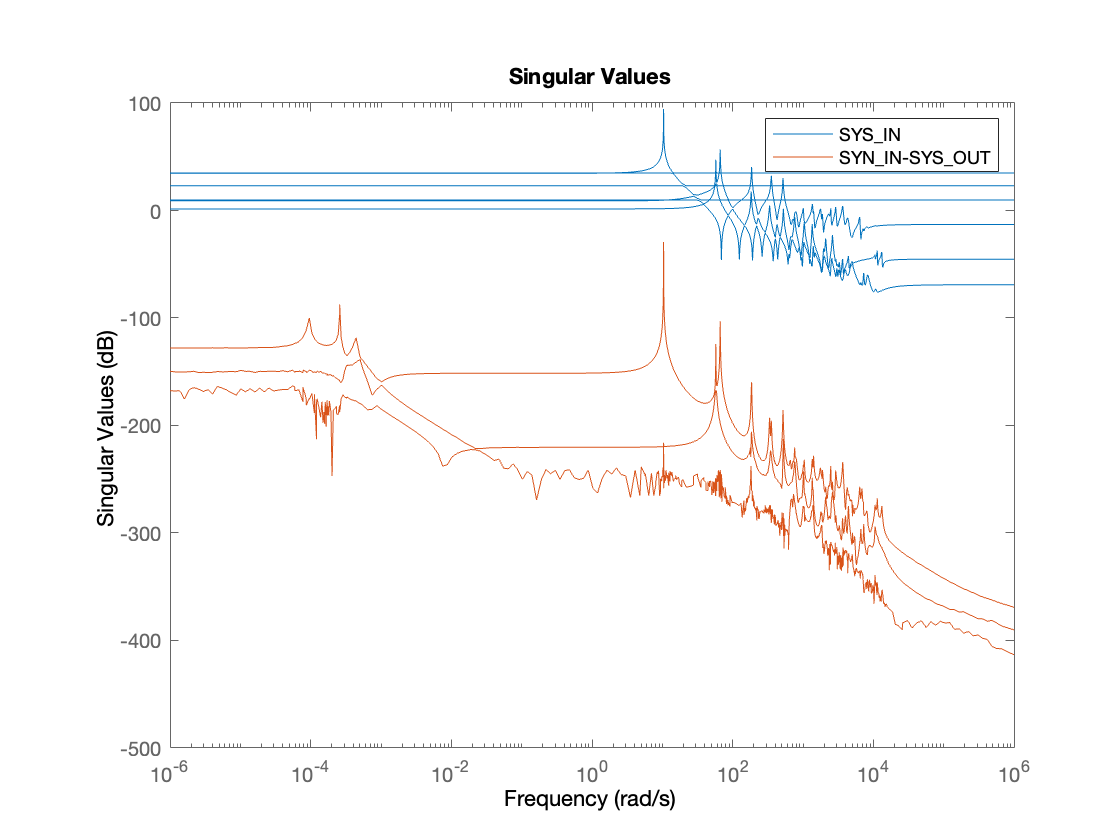

M_SAr=red_slow(M_SA,0.9);

Once reduced the model $\mathbf M^{\mathcal{SA}}_{P_{1_1}}(\mathrm s)$ is a $96$-th order model with $48$ flexible modes spread between $10$ an $13 000\,(rad/s)$.

For control design purpose, such a model can be reduced using a balanced reduction. The following MATLAB sequence reduced the model to a $20-th$ order model (10 modes) and compare it with full-order model in the frequency-domain.

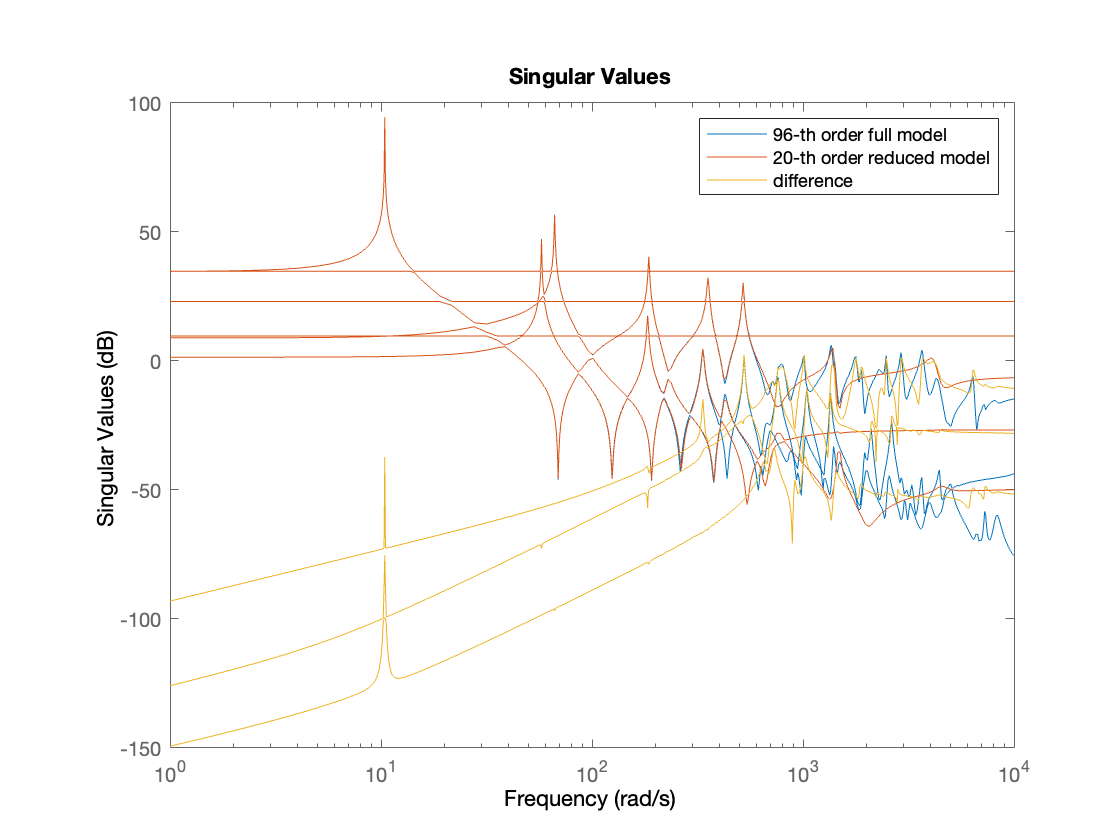

M_SArb=balreal(M_SAr);
M_SArbr=modred(M_SArb,[21:96]);
figure
sigma(M_SA,M_SArbr,M_SA-M_SArbr,{1,10000})
legend('96-th order full model','20-th order reduced model','difference')

## 4. Summary

The SDTlib can be used to model complex mechanisms of flexible bodies with closed-kinematic chains. The obtained model can be a high order model. When reducing it, it is recommended to proceed in 2 steps:

- first, reduce eigenvalues around $0$ due to kinematic constraints using a modal troncature (function `red_slow`) or a minimal realiization (function `minreal`). The number of eigenvalues to be reduced can be known by a kinematic analysis of the mechanism,

- second, reduce high frequency flexible modes using a balanced reduction.